% Created by: R.Holser (rholser@ucsc.edu)
% Created on: 21-Jun-2024
%
% Basic matlab code to illustrate accessing northern elephant seal tracking and diving 
% data and metadata from netCDF-4 files.

## Load metadata prior to loading data into memory

ncinfo pulls all information about netCDF file structure (groups, variables, attributes) into the workspace as a matlab structure.  

% Read in all information (metadata) from both .nc files
AllInfo_R=ncinfo('2017001_TrackTDR_RawCurated.nc'); %Level 1&2 data file
AllInfo_P=ncinfo('2017001_TrackTDR_Processed.nc'); %Level 3 data file

% Global attributes include all deployment and animal metadata and are found in
% MetaData_P.Attributes. However, the default loaded format is not easily 
% searchable. This loop created a new structure MetaData

% Initialize a new structure
MetaData = struct();

% Loop through each element in the original structure
for i = 1:length(AllInfo_P.Attributes)
    % Get the name and value
    name = AllInfo_P.Attributes(i).Name;
    value = AllInfo_P.Attributes(i).Value;
    % Convert the name to a valid field name
    name = matlab.lang.makeValidName(name);
    % Assign the value to the corresponding field in the new structure
    MetaData.(name) = value;
end

% Assign the new structure back to AllInfo_Pro.Attributes if wanted
AllInfo_P.Attributes = MetaData;
AllInfo_R.Attributes = MetaData;

% Show animalID, deploymentID, and TDR QC flag
disp ('Animal ID: ')

Animal ID: 


disp(MetaData.Animal_ID) %alternate: AllInfo_P.Attributes.Animal_ID

6018


disp ('Deployment ID: ')

Deployment ID: 


disp(MetaData.Deployment_ID) %alternate: AllInfo_P.Attributes.Deployment_ID

     2017001



disp ('TDR Quality: ')

TDR Quality: 


disp(MetaData.Data_TDR1_QCFlag) %alternate: AllInfo_P.Attributes.Data_TDR1_QCFlag

     1



## Load processed track into table

ncread(source,varname) is a simple command that allow you to read in data stored in specific variables within netCDF files using the file name and varibale name. For variables stored within groups or subgroups, varname is expressed as "/GROUP/VARIABLE" or "/GROUP/SUBGROUP/VARIABLE".

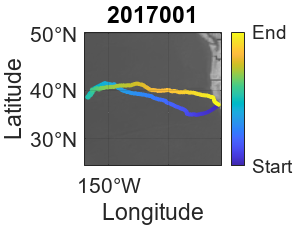

Date = ncread('2017001_TrackTDR_Processed.nc', "/TRACK/DATE"); % Date/Time of each location
Date = datetime(Date);  % Convert strings to datetime format
Lat = ncread('2017001_TrackTDR_Processed.nc', "/TRACK/LAT"); % Latitude
Lon = ncread('2017001_TrackTDR_Processed.nc', "/TRACK/LON"); % Longitude
% Combine variables into table
Track = table(Date,Lat,Lon);
clear Date Lat Lon
Track.DateNum = datenum(Track.Date);

% Plot map of track using geoscatter with color showing time change
figure
h=geoscatter(Track.Lat,Track.Lon,10,Track.DateNum,'filled');
geobasemap grayterrain
ax=gca;
ax.FontSize=16;
ax.Colormap=parula;
ax.Title.String=string(MetaData.Value("Deployment_ID")); % Pull Deployment_ID from MetaData for title
c=colorbar;
c.TickLabels=["Start","End"];
c.Ticks = [min(Track.DateNum),max(Track.DateNum)];
c.Label.String="Time of Trip";

## Load processed diving data (from full resolution record) into table

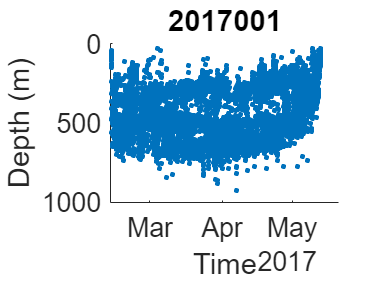

Date = ncread('2017001_TrackTDR_Processed.nc', "/TDR1/DATE"); % Date/time of start of each dive
Date = datetime(Date);  % Convert strings to datetime format
Lat = ncread('2017001_TrackTDR_Processed.nc', "/TDR1/LAT"); % Latitude of the start of each dive
Lon = ncread('2017001_TrackTDR_Processed.nc', "/TDR1/LON"); % Longitude of the start of each dive
Depth = ncread('2017001_TrackTDR_Processed.nc', "/TDR1/MAXDEPTH"); % Maximum depth of each dive
% Combine variables into table
Dives = table(Date,Depth,Lat,Lon);
clear Date Depth Lat Lon
Dives.DateNum = datenum(Dives.Date);

% Plot 2-D: Depth ~ Time figure
figure
scatter(Dives.Date, Dives.Depth,10,'filled')
ax=gca;
ax.YDir="reverse";
ax.FontSize=16;
ax.Title.String=string(MetaData.Value("Deployment_ID")); % Pull Deployment_ID from MetaData for title
ax.YLabel.String = "Depth (m)";
ax.XLabel.String = "Time";

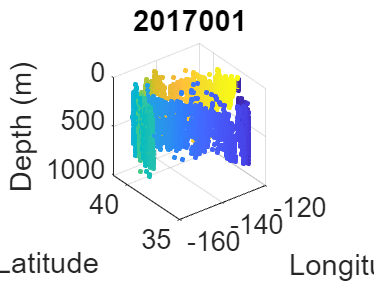


% Plot 3-D: Depth ~ LatxLon with color showing time change
figure
scatter3(Dives.Lon, Dives.Lat, Dives.Depth, 10, Dives.DateNum, 'filled')
ax=gca;
ax.ZDir="reverse";
ax.FontSize=16;
ax.Title.String=string(MetaData.Value("Deployment_ID")); % Pull Deployment_ID from MetaData for title
ax.ZLabel.String = "Depth (m)";
ax.YLabel.String = "Latitude";
ax.XLabel.String = "Longitude";

## Load ZOC'd full resolution TDR data

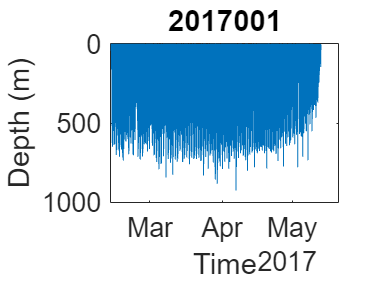

Date = ncread('2017001_TrackTDR_RawCurated.nc', "/CLEAN_ZOC_TDR1/DATE"); % Date/time of each depth
Date = datetime(Date, "ConvertFrom","datenum");  % Convert MATLAB serial date to datetime format
Depth = ncread('2017001_TrackTDR_RawCurated.nc', "/CLEAN_ZOC_TDR1/DEPTH"); % Depth
% Combine variables into table
TDR = table(Date,Depth);
clear Date Depth

% Plot 2-D: Depth ~ Time figure
figure
plot(TDR.Date, TDR.Depth)
ax=gca;
ax.YDir="reverse";
ax.FontSize=16;
ax.Title.String=string(MetaData.Value("Deployment_ID")); % Pull Deployment_ID from MetaData for title
ax.YLabel.String = "Depth (m)";
ax.XLabel.String = "Time";